## 1.

b = bit_gen(3, 4)

b = 3×4 int32 matrix
   1   1   0   1
   1   1   1   0
   0   0   1   1


## 2.

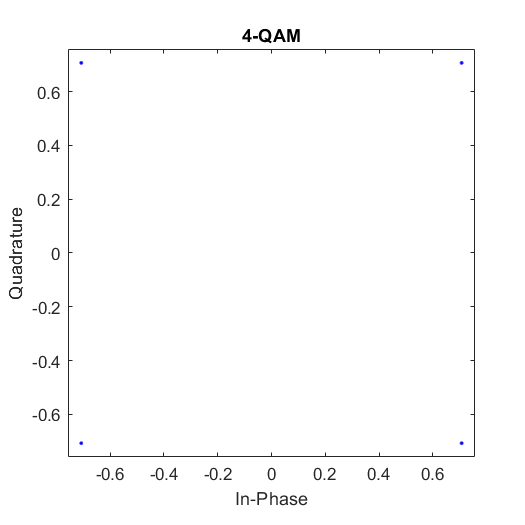

[cons1, Es_avg1] = constellation(4, 'qam');
scatterplot(cons1)
title('4-QAM')

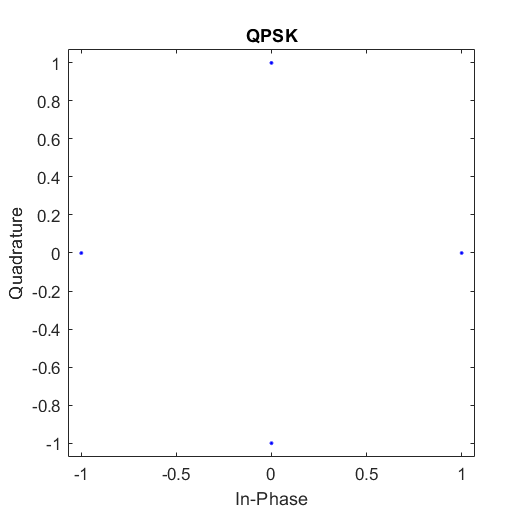


[cons2, Es_avg2] = constellation(4, 'psk');
scatterplot(cons2)
title('QPSK')

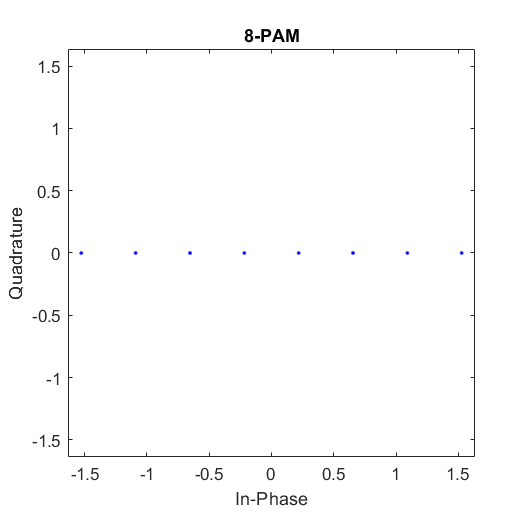


[cons3, Es_avg3] = constellation(8, 'pam');
scatterplot(cons3)
title('8-PAM')

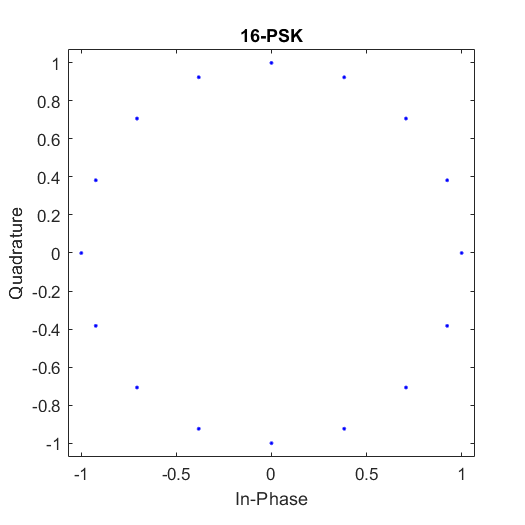


[cons4, Es_avg4] = constellation(16, 'psk');
scatterplot(cons4)
title('16-PSK')

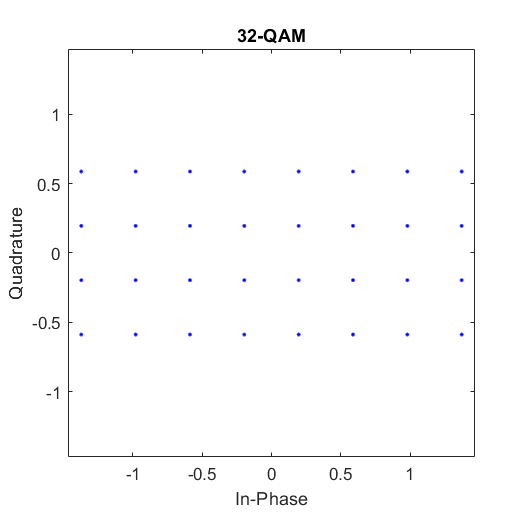


[cons5, Es_avg5] = constellation(32, 'qam');
scatterplot(cons5)
title('32-QAM')


sum(abs(cons4).^2)/16 %power

ans = 1

#### As last output shows, constellations have normalized average energy.

## 3.

### a.

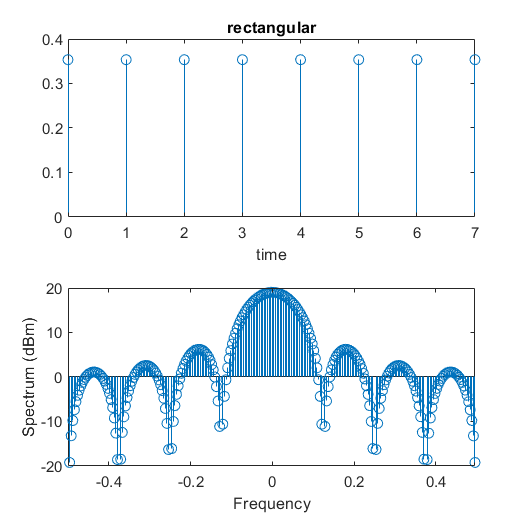

[p1, t1] = pulse_shape('rectangular', 1, 8);

sum(p1.^2) %power

ans = 1.0000

#### As shown above, the output signal has normalized energy.

### b.

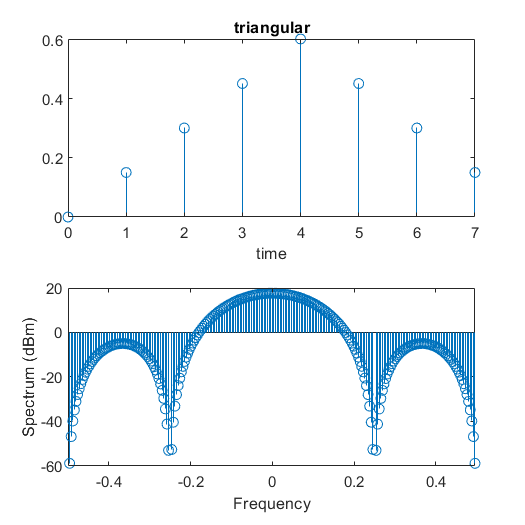

[p2, t2] = pulse_shape('triangular', 1, 8);

sum(p2.^2) %power

ans = 1.0000

### c.

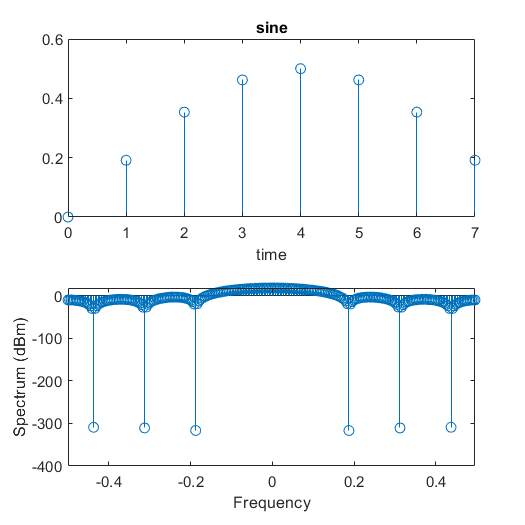

[p3, t3] = pulse_shape('sine', 1, 8);

sum(p3.^2) %power

ans = 1

## Functions Defenition:

### part 1.

function [b] = bit_gen(N, k)
b = int32(randi([0, 1], [N, k]));
end

### part 2.

function [cons, Es_avg] = constellation(M, modulation)
if strcmp(modulation, 'pam')
    Es_avg = (M^2 - 1)/3;
    cons = (-M+1:2:M-1).'/ sqrt(Es_avg);
elseif strcmp(modulation, 'psk')
    m = (1:M).';
    cons = cos(2*pi*(m-1)/M) + 1j * sin(2*pi*(m-1)/M);
elseif strcmp(modulation, 'qam')
    if mod(log2(M), 2) == 0
        m1 = log2(M) / 2;
        m2 = m1;
        v1 = 1j * (-sqrt(M)+1:2:sqrt(M)-1).';
        v2 = (-sqrt(M)+1:2:sqrt(M)-1).';
    else
        m1 = fix(log2(M) / 2);
        m2 = log2(M) - m1;
        v1 = 1j * (-2^m1+1:2:2^m1-1).';
        v2 = (-2^m2+1:2:2^m2-1);
    end
    cons = ones(M, 1);
    for k = 1:2^m2
        if mod(k, 2) == 0
            cons(2^m1 * (k-1) + 1:2^m1 * k, 1) = v1 + v2(k) * ones(2^m1, 1);
        else
            cons(2^m1 * (k-1) + 1:2^m1 * k, 1) = flip(v1) + v2(k) * ones(2^m1, 1);
        end
    end
    Es_avg = sum(abs(cons).^2) / M;
    cons = cons / sqrt(Es_avg);
end
Es_avg = 1;
end

### part 3.

function [p, t] = pulse_shape(pulse_name, fs, smpl_per_symbl, varargin)
Ts = smpl_per_symbl * fs;
t = (0:smpl_per_symbl-1)/fs;
if strcmp(pulse_name, 'rectangular')
    p = ones(smpl_per_symbl, 1);
elseif strcmp(pulse_name, 'triangular')
    p = (max(Ts/2 - abs(t-Ts/2), 0)).';
elseif strcmp(pulse_name, 'sine')
    p = sin(pi*t.'/Ts);
end
p = p / sqrt(sum(p.^2));
discrete_plot(p, t, fs, pulse_name)
end

#### plot:

function [] = discrete_plot(p, t, fs, pulse_name)
subplot(2, 1, 1);
stem(t, p)
xlabel('time')
title(pulse_name)

subplot(2, 1, 2);
Pf = fftshift(fft(p, 256));
freq = (0:255)/256*fs - fs/2;
Pf_dBm = 10 * log10((abs(Pf)).^2 / 100) + 30;
stem(freq, Pf_dBm)
xlim([freq(1),freq(end)])
xlabel('Frequency')
ylabel('Spectrum (dBm)')
end